# 1D & 3DTarget Tracking

**Author**: Michel Barbeau

**Version**: February 14, 2024

## 1D Sample Execution 1

`Number of instants:  10`

`Target positions:  [1 3 5 2 1 1 3 0 0 6]`

`Info: {'constraint_labels': ['p_6', 'min_3', 'l_6', 'l_5', 'p_0', 'min_8', 'min_2', 'p_5', 'p_8', 'u_4', 'l_3', 'p_1', 'p_4', 'l_1', 'min_1', 'l_8', 'l_2', 'min_6', 'p_7', 'u_9', 'u_0', 'u_2', 'u_1', 'u_7', 'u_8', 'min_5', 'u_6', 'p_2', 'u_5', 'min_9', 'l_7', 'l_4', 'u_3', 'p_3', 'min_4', 'min_7', 'l_9', 'min_0', 'l_0'], 'qpu_access_time': 31901, 'charge_time': 4687119, 'run_time': 4687119, 'problem_id': 'da018e96-2982-454e-b539-0630a499919a'}`

`Sample: {'v_0': -2.0, 'v_1': 2.0, 'v_2': 1.0, 'v_3': -1.0, 'v_4': 0.0, 'v_5': -2.0, 'v_6': 1.0, 'v_7': 0.0, 'v_8': 2.0, 'v_9': 2.0, 'x_0': 3.0, 'x_1': 1.0, 'x_2': 3.0, 'x_3': 4.0, 'x_4': 3.0, 'x_5': 3.0, 'x_6': 1.0, 'x_7': 2.0, 'x_8': 2.0, 'x_9': 4.0}`

`Tracking score: 40.0`

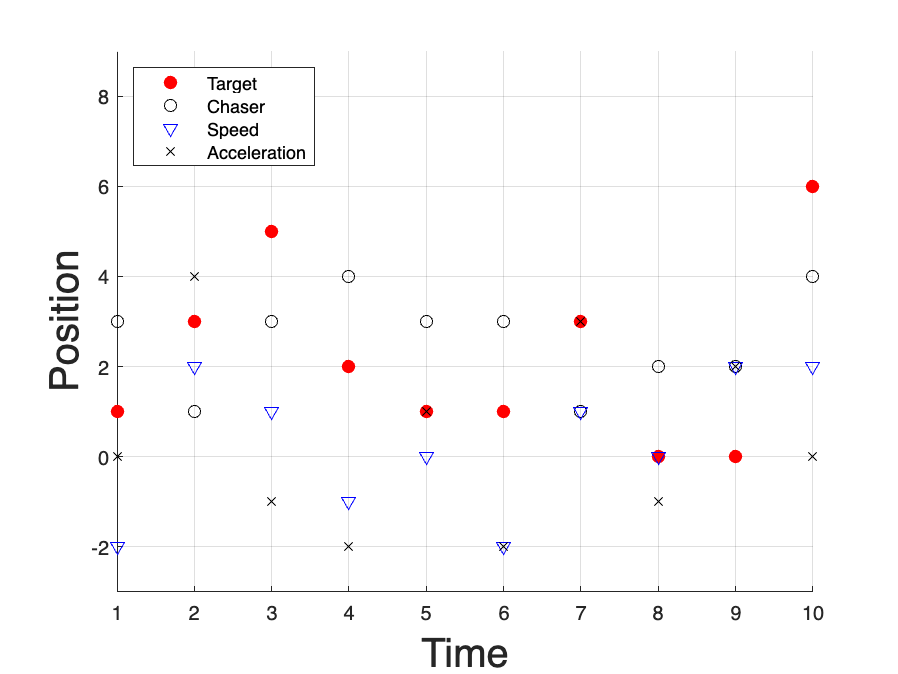

% number of instants
n = 10;
% Speed
v = [-2 2 1 -1 0 -2 1 0 2 2]; % last item not used in constraints
figure;
% title('1D Target Tracking');
hold on;  
% Target
plot(1:10,...
     [1 3 5 2 1 1 3 0 0 6],'.','markersize',20,'color','red');
% Chaser
plot(1:10,...
     [3 1 3 4 3 3 1 2 2 4],'o','color','black');
% Speed
plot(1:10,...
     v,'v','color','blue');
legend('Target','Chaser','Speed','Location','southeast')
% Acceleration
plot(1:10,...
     [0 v(2:end)-v(1:end-1)],'kx');
legend('Target','Chaser','Speed','Acceleration','Location','northwest')
ylim([-3 9])
yl = ylabel('Position');
set(yl, 'FontSize', 20) 
xl = xlabel('Time');
set(xl, 'FontSize', 20) 
% ylim([0 34]);
hold off;
grid on;
f = gcf;
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
exportgraphics(f,'1DTargetTracking.png');

## 3D Sample Execution

Number of instants:  10

Deltas:

 [[ 0  0 -1  0  1 -1  1 -1  0  1]

 [ 1 -1 -1  1 -1  1  1  1  0  1]

 [-1 -1  0  1  1  0  1 -1  0 -1]]

Target positions:

 [[7 7 6 6 7 6 7 6 6 7]

 [6 5 4 5 4 5 6 7 7 8]

 [4 5 5 6 7 7 8 7 7 6]]

Info: {'constraint_labels': ['xmin_0', 'xmin_2', 'pz_5', 'px_4', 'xmax_0', 'px_8', 'pz_3', 'py_2', 'xmax_2', 'px_3', 'pz_6', 'px_7', 'xmin_3', 'xmin_8', 'py_0', 'xmax_6', 'px_6', 'py_4', 'pz_0', 'xmin_1', 'xmax_3', 'xmax_7', 'py_3', 'py_6', 'px_5', 'pz_8', 'py_8', 'xmin_4', 'xmax_8', 'py_1', 'xmin_6', 'xmin_9', 'pz_1', 'px_2', 'px_0', 'xmin_5', 'xmin_7', 'px_1', 'py_7', 'xmax_9', 'pz_2', 'pz_7', 'xmax_1', 'pz_4', 'xmax_4', 'xmax_5', 'py_5'], 'qpu_access_time': 32087, 'charge_time': 5000000, 'run_time': 5433369, 'problem_id': '6ba40bb7-6369-43cc-82af-2c29e05737c1'}

Sample: {'vx_0': 0.0, 'vx_1': -6.0, 'vx_2': -7.0, 'vx_3': 0.0, 'vx_4': 0.0, 'vx_5': -1.0, 'vx_6': 0.0, 'vx_7': 2.0, 'vx_8': -2.0, 'vx_9': -3.0, 'vy_0': -1.0, 'vy_1': 1.0, 'vy_2': 0.0, 'vy_3': 0.0, 'vy_4': 1.0, 'vy_5': -1.0, 'vy_6': 1.0, 'vy_7': 1.0, 'vy_8': 1.0, 'vy_9': 3.0, 'vz_0': 1.0, 'vz_1': 0.0, 'vz_2': 0.0, 'vz_3': 1.0, 'vz_4': 1.0, 'vz_5': 0.0, 'vz_6': 0.0, 'vz_7': -1.0, 'vz_8': -1.0, 'vz_9': -1.0, 'x_0': 7.0, 'x_1': 7.0, 'x_2': 7.0, 'x_3': 7.0, 'x_4': 7.0, 'x_5': 7.0, 'x_6': 6.0, 'x_7': 6.0, 'x_8': 8.0, 'x_9': 6.0, 'y_0': 5.0, 'y_1': 4.0, 'y_2': 5.0, 'y_3': 5.0, 'y_4': 5.0, 'y_5': 6.0, 'y_6': 5.0, 'y_7': 6.0, 'y_8': 7.0, 'y_9': 8.0, 'z_0': 5.0, 'z_1': 6.0, 'z_2': 6.0, 'z_3': 6.0, 'z_4': 7.0, 'z_5': 8.0, 'z_6': 8.0, 'z_7': 8.0, 'z_8': 7.0, 'z_9': 6.0}

Tracking score: 45.0

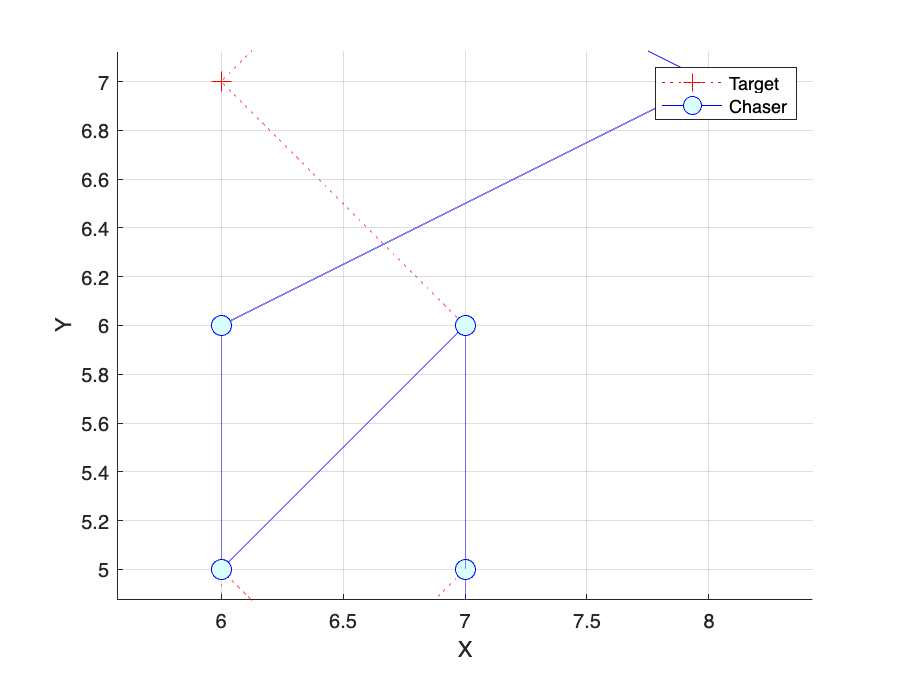

clear;
figure;
% Target positions
X = [7 7 6 6 7 6 7 6 6 7];
Y = [6 5 4 5 4 5 6 7 7 8];
Z = [4 5 5 6 7 7 8 7 7 6];
hold on;  
plot3(X,Y,Z,':+','Color','r','MarkerSize',10,...
    'MarkerFaceColor','red')
% Chaser position
CX = [7 7 7 7 7 7 6 6 8 6];
CY = [5 4 5 5 5 6 5 6 7 8];
CZ = [5 6 6 6 7 8 8 8 7 6];
plot3(CX,CY,CZ,'-o','Color','b','MarkerSize',10,...
     'MarkerFaceColor','#D9FFFF')
legend('Target','Chaser');
hold off;
grid on
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')
zlim([4 8.5])
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
f = gcf;
exportgraphics(f,'3DTargetTracking.png');

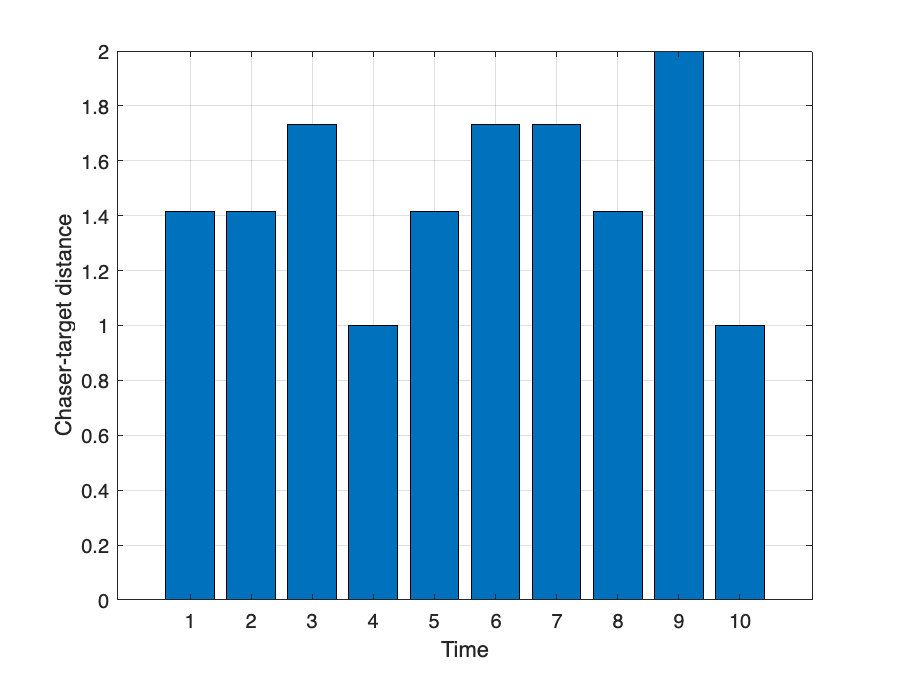

dx = zeros(1, length(X));
for i=1:length(dx);
    dx(i) = sqrt( (X(i)-CX(i))^2+(Y(i)-CY(i))^2+(Y(i)-CY(i))^2 );
end
figure
bar(dx)
xlabel('Time')
ylabel('Chaser-target distance')
grid on
cd '/Users/michelbarbeau/Dropbox/MyProjects/2024/D-Wave'
f = gcf;
exportgraphics(f,'3DChaserTargetDistance.png');